Sc0 = 240;
Sa0 = 740;
Ic0 = 10;
Ia0 = 10;
Ec0 = 0;
Ea0 = 0;
Rc0 = 0;
Ra0 = 0;
Nc0 = Sc0 + Ic0 + Ec0 + Rc0;
Na0 = Sa0 + Ia0 + Ea0 + Ra0;
daily = 1:1:365;
init_cond = [Sc0, Sa0, Ec0, Ea0, Ic0, Ia0, Rc0, Ra0, Nc0, Na0];
par = [0.00027 0.005 0.01 0.00005 0.074 0.1 0.3 0.2 0.0067 0.00018 0.000033 0.0067];%.00027 0.01 0.01 0.00005 0.074 0.1 0.3 0.2

[t,yc]=ode45(@SEIR_model_states_AdultChild_infectE,daily,init_cond,[],[par(1), par(2), par(3), par(4), par(5), par(6), par(7), par(8), par(9), par(10), par(11), par(12)]);
[Pc,t_index] = max(yc(:,5));
Ptc = t(t_index)

Ptc = 1

[t,ya]=ode45(@SEIR_model_states_AdultChild_infectE,daily,init_cond,[],[par(1), par(2), par(3), par(4), par(5), par(6), par(7), par(8), par(9), par(10), par(11), par(12)]);
[Pa,t_index] = max(ya(:,6));
Pta = t(t_index)

Pta = 44

figure
hold on
title('SEIR Adult Child Infectious E R_0 = 3.4153')
l1=plot(t,ya(:,6), 'magenta')

l1 =   Line with properties:

              Color: [1 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
              YData: [10 9.2697 8.9987 9.1022 9.5200 10.2094 11.1441 12.3061 13.6877 15.2879 17.1083 19.1563 21.4430 23.9793 26.7758 29.8470 33.2077 36.8682 40.8348 45.1057 49.6901 54.5936 59.8082 65.3128 71.0733 77.0427 83.1869 89.4778 95.8693 … ]

  Show all properties


l2=plot(t, yc(:,5), 'cyan')

l2 =   Line with properties:

              Color: [0 1 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
              YData: [10 9.2926 8.6532 8.0724 7.5432 7.0598 6.6180 6.2140 5.8449 5.5083 5.2022 4.9249 4.6752 4.4518 4.2537 4.0803 3.9308 3.8047 3.7016 3.6210 3.5627 3.5264 3.5117 3.5185 3.5461 3.5942 3.6623 3.7497 3.8555 3.9786 4.1178 4.2717 4.4389 … ]

  Show <a href="matlab:if exist('l2', 'var'), matlab.graphics.internal.getForDisplay('l2', l2, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('l2'), end">all properties<

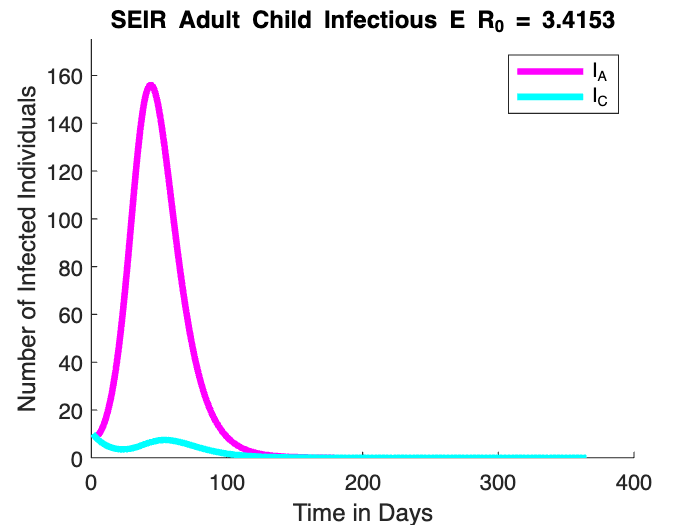

l1.LineWidth=3;
l2.LineWidth=3;
xlabel('Time in Days')
ylabel('Number of Infected Individuals')
axis([0 400 0 175])
legend('I_A','I_C')
hold off

betaaa = 0.00027;
betacc = 0.01;
betaac = 0.01;
betaca = 0.00005;
gammaa = 0.074;
gammac = 0.1;
epsilonc = 0.3;
epsilona = 0.2;
Nc = 250;
Na = 750;
xicc = 0.0067;
xiaa = 0.00018;
xica = 0.000033;
xiac = 0.0067;
mu = 0.00008;
f = 0.0005;

eig1 = xicc/(epsilonc+f)+betacc*epsilonc/((epsilonc+f)*(f+gammac))+Nc*f*xiac/(Na*(epsilonc+f)*(epsilona+mu))+Nc*betaac*(epsilona*f^2+epsilona*epsilonc*f+epsilona*f*gammac+epsilonc*f*mu)/(Na*(epsilonc+f)*(f+gammac)*(epsilona+mu)*(gammaa+mu));
eig2 = Nc*xiac/(Na*(epsilona+mu))+Nc*betaac*epsilona/(Na*(epsilona+mu)*(gammaa+mu));
eig3 = Na*xica/(epsilonc+f)+Na*betaca*epsilonc/((epsilonc+f)*(f+gammac))+ Na*f*xiaa/((epsilonc+f)*(epsilona+mu))+Na*betaaa*(epsilona*f^2+epsilona*epsilonc*f+epsilona*f*gammac+epsilonc*f*mu)/((epsilonc+f)*(f+gammac)*(epsilona+mu)*(gammaa+mu));
eig4 = Na*xiaa/(epsilona+mu)+Na*betaaa*epsilona/((epsilona+mu)*(gammaa+mu));
Ro = eig1/2 + eig4/2 + (eig1^2 - eig1*eig4*2 + eig4^2 + eig2*eig3*4).^(1/2)/2

Ro = 3.4153

    function [dx]  = SEIR_model_states_AdultChild_infectE(t,x,z)

    %parameters to be estimated
    betaaa = z(1); %0.00027; %5*10^-7 to 2*10^-5
    betacc = z(2); %0.01; %0.1 to 1
    betaac = z(3); %0.01; %.05 to 1 <betacc
    betaca = z(4); %0.00005; % 1*10^-8 to 5*10^-7
    gammac = z(5); %0.1; % 0.1 %.02 to 1
    gammaa = z(6); %0.074; % 0.074 % .01 to 1
    epsilonc = z(7); %0.3;% 0.3 % .04 to 1
    epsilona = z(8); %0.2;% 0.2 % .02 to 1
    xicc = z(9); %0.0067;
    xiaa = z(10); %0.00018;
    xica = z(11); %0.000033;
    xiac = z(12); %0.0067;
    mu = 0.00008; %4*10^-5 to 8*10^-5
    f = 0.0005; %1*10^-4 to 5*10^-4
    Nc0 = 250;
    Na0 = 750;


      
    Sc = x(1); Sa = x(2); Ec = x(3); Ea = x(4); Ic = x(5); Ia = x(6); Rc = x(7); Ra = x(8); Nc = x(9); Na = x(10);
    
   %IC: Total N=1000. S(0)=990 E(0)=0 I(0)=10  R(0)=0
   
   
    dx = zeros(10,1);
    %dSc
    dx(1) = mu*Na - (betacc*Ic/Nc + betaac*Ia/Na + xicc*Ec/Nc +xiac*Ea/Na)*Sc - f*Sc;
    %dSa 
    dx(2) = f*Sc - (betaaa*Ia + betaca*Ic + xiaa*Ea + xica*Ec)*Sa - mu*Sa;
    %dEc
    dx(3) = (betacc*Ic/Nc + betaac*Ia/Na + xicc*Ec/Nc +xiac*Ea/Na)*Sc - epsilonc*Ec - f*Ec;
    %dEa
    dx(4) = (betaaa*Ia + betaca*Ic + xiaa*Ea + xica*Ec)*Sa - epsilona*Ea + f*Ec - mu*Ea;
    %dIc
    dx(5) = epsilonc*Ec - f*Ic - gammac*Ic;
    %dIa 
    dx(6) = f*Ic+ epsilona*Ea - gammaa*Ia - mu*Ia;
    %dRc
    dx(7) = gammac*Ic - f*Rc;
    %dRa
    dx(8) = gammaa*Ia +f*Rc - mu*Ra;
     %dNc
    dx(9) = mu*Na - f*Nc;
    %dNa
    dx(10) = f*Nc - mu*Na;

    
end